# Introduction to Symbolic Toolbox

The MathWorks Symbolic Toolbox allows you to use MATLAB to solve equations. You can use the Symbolic Toolbox to check your work as you learn new math and new equations.  This introduction shows you the basics of the Symbolic Toolbox.

## Symbolic Variables and Equation Variables

Symbolic variables allow you to create equations and solve them.  Symbolic variables don't store numbers, they store equations and constants.

We declare Symbolic variables using the `syms` command:

syms y x;

Now we have symbolic variables named `x` and `y.  We can use them to store an equation in a variable. For example, let's capture this equation:`


$$y=2x$$


in a variable named `eq`.

eq = y == 2*x

$$eq = y=2\,x$$

## Plotting an equation

Now that we have an equation, we can ask MATLAB to plot the equation using `fimplicit()`.  The `fimplicit()` function creates a graph of a function by providing the values for `x`.  The plot for `y = 2x`

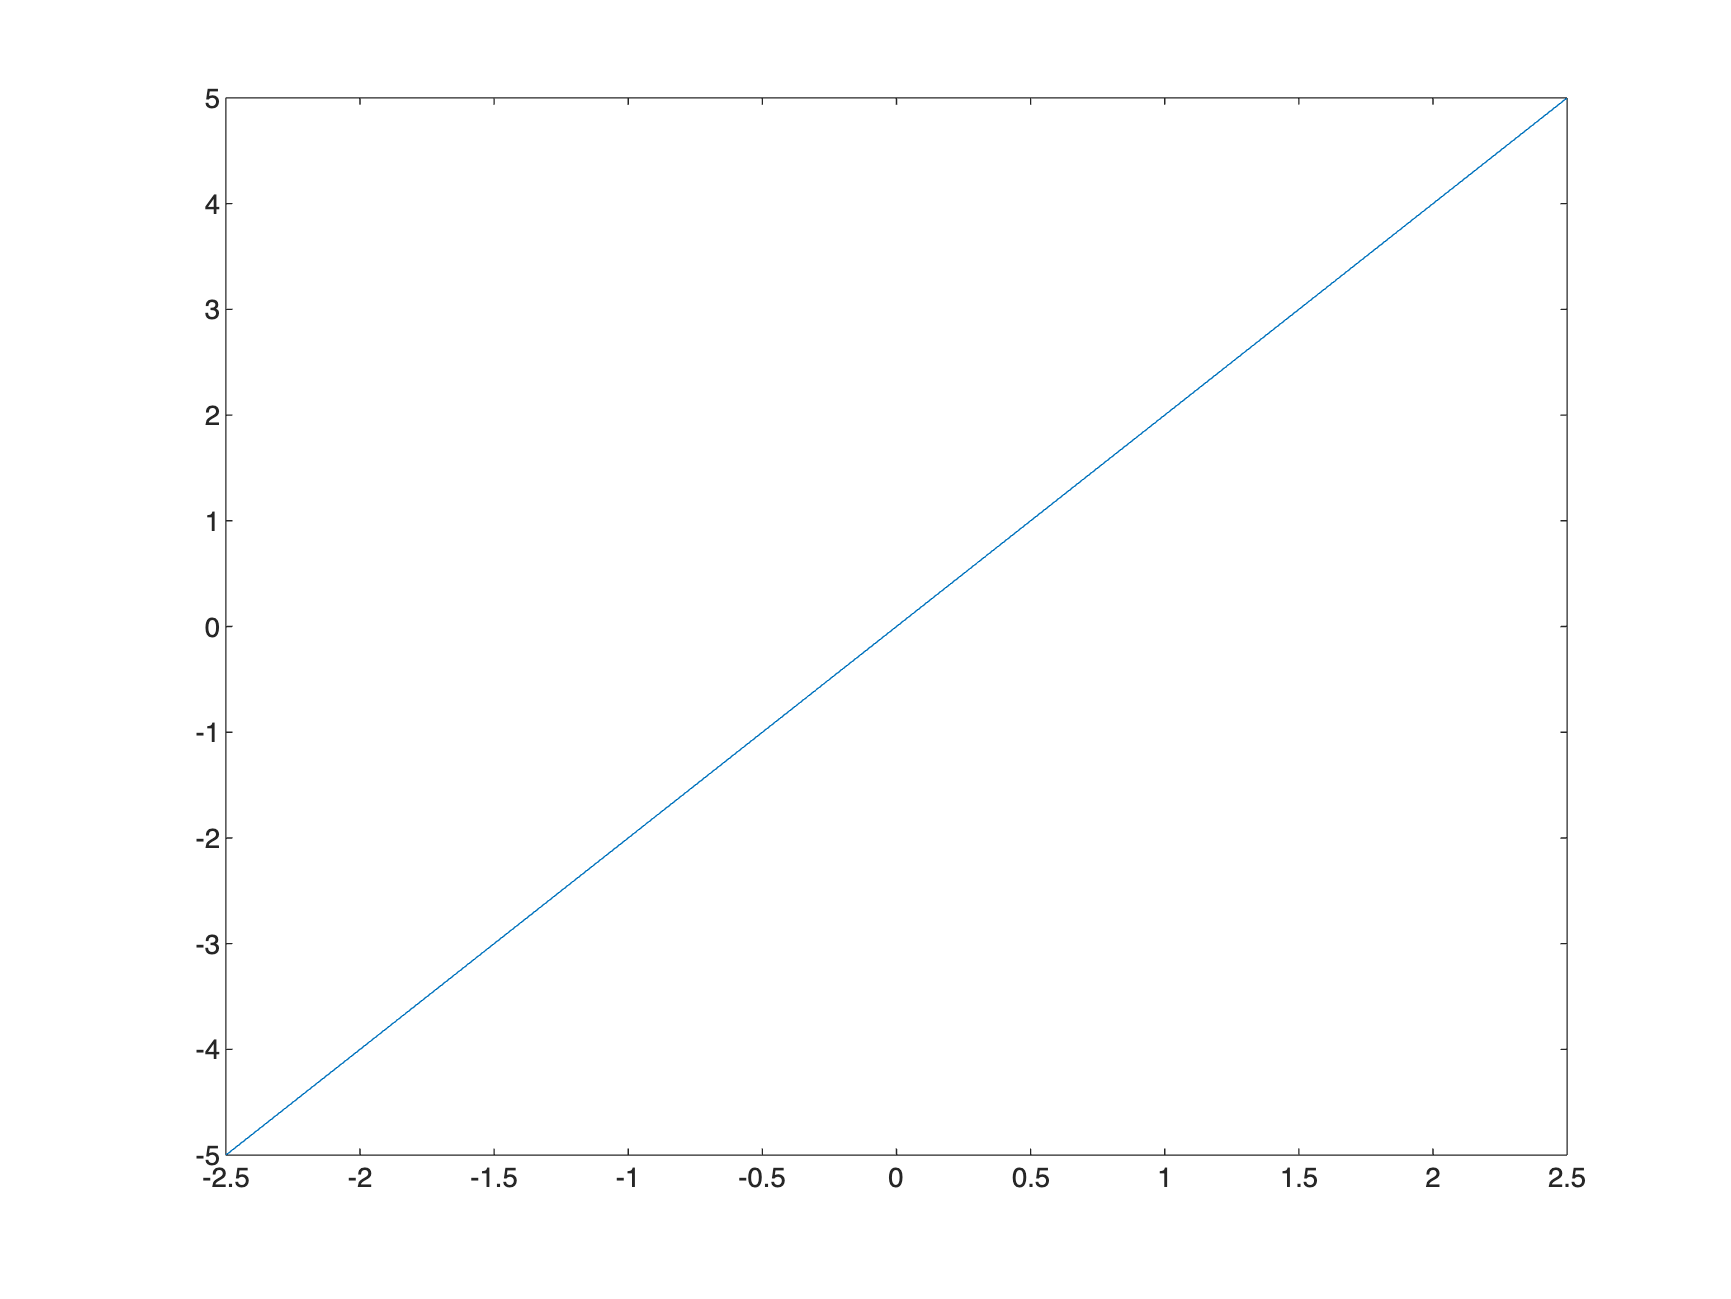

fimplicit(eq)

## Solving an equation for a specific value

Our equation reads `y == 2*x` which means that the symbolic variable y is 2 times the symblic variable.  If we set `x` or `y` to a value we can solve for the other.  For example, let's set `y` to `6` and find `x` using the `solve()` function.

The `solve()` function takes the equation variable and a constraint and returns the solved values.

result = solve(eq, y==6)

result = struct with fields:
    x: 3
    y: 6


The `result` variable contains values for `x` and `y`.  As you would expect, `x` is 3 when `y` is 6.

## Equations with multiple variables

Equations capture relationships between any number of range variables.  In our example above, we had one range variable named `x`. When we set `x` to a value we know `y`.  But, we can have other relationships such as the relationship between distance and speed. 

syms distance speed time
distEQ = distance == speed * time

$$distEQ = \mathrm{distance}=\mathrm{speed}\,\text{time}$$

Now that we have this equation, we can find answers to distance/speed problems.

### Solving homework questions

*Carl drives his car for one hour at 50 kilometers per hour.  How far has Carl driven?*

answer = solve(distEQ, speed == 50, time == 1)

answer = struct with fields:
    distance: 50
       speed: 50
        time: 1


We see that Carl has driven fifty kilometers in one hour (we will cover units later.)

*Sofia has been driving for 22 hours and has travelled 200 kilometers.  How fast was Sophia driving?*

answer = solve(distEQ, time == 22, distance == 200)

answer = struct with fields:
    distance: 200
       speed: 100/11
        time: 22


Here we see the difference between the Symbolic Toolbox and a simple calculator.  With a calculator, you would put the numbers into the equation like this:


$$200=\textrm{speed}*22\;\textrm{hours}$$


Then you would divide 200 by 22 to get the speed as a floating point number.

The Symbolic Toolbox solves the equation for you but does not do the math for you.  So the answer is `200/22` or, simplified `100/11`. 

If you want the actual number, you need to covert this operation to *variable precision arithmetic* using the function `vpa()`.

spd = vpa(answer.speed)

$$spd = 9.0909090909090909090909090909091$$

Of course, if you were to provide this answer on a Physics test you would get only 2 points of 3 because you left off the units.  So lets add units to our equations.

## Using Units

Equations describe the relationship between values, such as speed, time, and distance.  But, units connect those relationships to the real world. We can add units to the values we send to the `solve()` function to get correct units at the end.

The Symbolic Toolbox stores all  units in a collection named `symunit`.  A collection is like a struct in that it contains many values that you access using a dot. In this case, the values are units.  `symunit` is too long to type, so we'll set it equal to `u`.

u = symunit; % create a short reference to units

Now when we do our homework the Symbolic Toolbox figures out the units.

*Aisha drove 23 kilometers in 3.2 hours.  What was Aisha's average speed?*

Remember our equation:

distEQ = distance == speed * time

$$distEQ = \mathrm{distance}=\mathrm{speed}\,\text{time}$$

We solve the equation using the numbers *and units* from the problem.  We add units to our solution by multplying our numbers by their units.  (This multiplication is actually what we are doing when we add units to a number.  That is why the units can cancel out.)

answer = solve(distEQ, distance == 23*u.km, time == 3.2*u.h)

answer = struct with fields:
    distance: 23*[km]
       speed: (115/16)*([km]/[h])
        time: (16/5)*[h]


vpa(answer.speed)

$$ans = 7.1875\,\frac{\mathrm{km}}{h}$$